## Extract Resources per Request using Map Reduce

We want to extract the resources per request for each service. Ressources being CPU and Memory. This would allow us to adjust the "stress/loader" functions of the service-cell to reproduce the original service behaviour in terms of ressource consumption.

Requires the exported service samples of sample_services/alibaba2022ms.mlx to limit the inspected microservices.

Note ahead: The sampling rate is too low and not all microservices in use reported their metrics, so this approach has been discontinued.

### Load Service Samples

Load the MAT file to extract the invovled microservices, This will reduce computing time as we do not care about all entries.

[service_samples_export_file, ~, ~, ~, ~, ~] = config();
load('-mat', service_samples_export_file);
service_samples = export;
clear export;
disp(service_samples);

     service_id      cluster    trace_factor                                                                         involved_ms                                                                     
    _____________    _______    ____________    _____________________________________________________________________________________________________________________________________________________

    "S_79946648"        1         0.098634      {["MS_40139"    "MS_45753"    "USER"                                                                                                               ]}
    "S_62583430"        1         0.098634      {["MS_58809"    "MS_9076"    "USER"                                                                                                                ]}
    "S_6505908"         1         0.098634      {["MS_13825"    "MS_578

List of services we are interested in

clear service_samples_export_file;
% All MS in once list (with duplicates)
involved_ms_with_duplicates = horzcat(service_samples.involved_ms{:})';
% Unique List (but still has 'USER' ms)
involved_ms_unique_incl_user = unique(involved_ms_with_duplicates);
% Unique clean list without 'USER'
involved_ms = involved_ms_unique_incl_user(~strcmp(involved_ms_unique_incl_user, "USER"))
clear involved_ms_with_duplicates;
clear involved_ms_unique_incl_user;

### Parallelism

Parts of this script profit from parallel execution (requires Parallel Computing Toolbox)

**Run only one of two sections below...**

### Enabling parallel computing

Run this scetion to (re-)enable parallel mapreducing

Note: The debugger will not work within map-reduce parts while this is ON

mapreducer(gcp);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


### Disabling parallel computing

Run this scetion to disable parallel mapreducing

Note: This will allow the debugging of map-reduce parts.

mapreducer(0);

## Actual Script below

### Request Counts at metric sampling intervals

Prepare selected columns for Trace CSV reading

[trace_header, trace_formats] = trace_constants();
ignore_columns = ["trace_id", "service", "rpc_id", "rpc_type", "upstream_ms", "upstream_instance", "interface"];
used_col_idx = ~ismember(trace_header, ignore_columns);
trace_selected_cols = trace_header(used_col_idx);
trace_selected_formats = trace_formats(used_col_idx);

clear trace_formats;
clear trace_vartypes;
clear ignore_columns;

Create a datastore referencing the trace CSV(s) we want to process.

[trace_location, trace_header_lines] = trace_config();

trace_ds = tabularTextDatastore( ...
    trace_location, ...
    "NumHeaderLines", trace_header_lines, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...
    "MissingValue", 0, ...
    "VariableNames", trace_header, ...
    "SelectedFormats", trace_selected_formats, ...
    "SelectedVariableNames", trace_selected_cols);

limit_hour = 12;
if height(trace_ds.Files) > limit_hour*20
    fprintf("Limiting used traces to the first %d hour(s)", limit_hour)
    trace_ds.Files = trace_ds.Files(1:limit_hour*20);
end

Limiting used traces to the first 12 hour(s)


clear limit_hour;
clear trace_selected_cols;
clear trace_location;
clear trace_header_lines;
clear trace_selected_formats;
preview(trace_ds)

ans = 8×4 table
    timestamp     downstream_ms     downstream_instance     response_time
    __________    _____________    _____________________    _____________

    {'115352'}    {'MS_71712'}     {'MS_71712_POD_244' }      {'2.0' }   
    {'86450' }    {'MS_24094'}     {'MS_24094_POD_5168'}      {'5.0' }   
    {'86450' }    {'MS_24094'}     {'MS_24094_POD_5168'}      {'5.0' }   
    {'155753'}    {'MS_67455'}     {'MS_67455_POD_222' }      {'9.0' }   
    {'90649' }    {'UNKNOWN' }     {'UNKNOWN'          }      {'18.0'}   
    {'90664' }    {'MS_10343'}     {'MS_10343_POD_5'   }      {'0.0' }   
    {'167154'}    {'MS_60125'}     {'MS_60125_POD_5'   }      {'1.0' }   
    {'152182'}    {'MS_66701'}     {'MS_66701_POD_10'  }      {'1.0' }   


We want to find out how many calls happen just before a MS metric sampling point, so we can extract how many resources are being used by a specific service per call and as baseline.

- Only takes traces where downstream_ms is a member of 'involved_ms'

- Only takes traces where the request is ongoing at the sampling timestamp

% every 60s
resource_sampling_interval_ms = 60 * 1000;
% wrap mapper function to pass variable context
mapFunc = @(a, b, c)trace_mapper(a, b, c, involved_ms, resource_sampling_interval_ms);
reduceFunc = @(a, b, c)trace_reducer(a, b, c);
tic
trace_metrics_ds = mapreduce(trace_ds, mapFunc, reduceFunc, 'OutputFolder', './results');

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
Parallel mapreduce execution on the parallel pool:
********************************
*      MAPREDUCE PROGRESS      *
********************************
Map   0% Reduce   0%
Map   1% Reduce   0%
Map   2% Reduce   0%
Map   3% Reduce   0%
Map   4% Reduce   0%
Map   5% Reduce   0%
Map   6% Reduce   0%
Map   7% Reduce   0%
Map   8% Reduce   0%
Map   9% Reduce   0%
Map  10% Reduce   0%
Map  11% Reduce   0%
Map  12% Reduce   0%
Map  13% Reduce   0%
Map  14% Reduce   0%
Map  15% Reduce   0%
Map  16% Reduce   0%
Map  17% Reduce   0%
Map  18% Reduce   0%
Map  19% Reduce   0%
Map  20% Reduce   0%
Map  21% Reduce   0%
Map  22% Reduce   0%
Map  23% Reduce   0%
Map  24% Reduce   0%
Map  25% Reduce   0%
Map  26% Reduce   0%
Map  27% Reduce   0%
Map  28% Reduce   0%
Map  29% Reduce   0%
Map  30% Reduce   0%
Map  31% Reduce   0%
Map  32% Reduce   0%
Map  33% Reduce   0%
Map  34% Reduce   0%
Map  

toc

Elapsed time is 9856.012898 seconds.


clear empty_table;
clear col_idx_trace_id;
clear mapFunc;
clear reduceFunc;

### Read result and prepare table to match with metrics

e.g. for each entry we want to have the corresponding sampling timestamp

trace_metrics = prepare_trace_metrics(readall(trace_metrics_ds));

### Read Metric Data

Create a datastore referencing the metric CSV(s) we want to process.

[ms_metrics_header, ms_metrics_formats, ~] = constants();
[~, ms_metrics_location, ms_metrics_header_lines, ~, ~, ~] = config();
metrics_ds = tabularTextDatastore(ms_metrics_location, "NumHeaderLines", ms_metrics_header_lines, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...
    "MissingValue", 0, ...
    "VariableNames", ms_metrics_header, ...
    "SelectedFormats", ms_metrics_formats, ...
    "SelectedVariableNames", ms_metrics_header);

clear ms_metrics_header;
clear ms_metrics_formats;
clear ms_metrics_location;
clear ms_metrics_header_lines;
clear ms_metrics_selected_formats;
prev_metrics_ds = copy(metrics_ds);
reset(prev_metrics_ds);
prev_metrics_ds.ReadSize = 10;
read(prev_metrics_ds)

ans = 10×6 table
    timestamp      ms_name          ms_instance_id          node_id        cpu_utilization    memory_utilization
    _________    ____________    ____________________    ______________    _______________    __________________

      300000     {'MS_68185'}    {'MS_68185_POD_91' }    {'NODE_20236'}        0.17238             0.66236      
      420000     {'MS_25215'}    {'MS_25215_POD_372'}    {'NODE_36528'}       0.085708             0.43286      
      720000     {'MS_31285'}    {'MS_31285_POD_916'}    {'NODE_23966'}        0.44523             0.57209      
      780000     {'MS_42019'}    {'MS_42019_POD_38' }    {'NODE_34880'}       0.091057             0.52934      
      900000     {'MS_9482' }    {'MS_9482_POD_332' }    {'NODE_45529'}        0.17766             0

clear prev_metrics_ds;

### Filter MsMetrics using Map Reduce

For the services we care about and within the timelimit we want.

[~, ~, ~, ms_metrics_max_timestamp, ~, metrics_output_file] = config();

% Wrap mapFun to pass involved_ms
mapFunc = @(a, b, c)metrics_mapper(a, b, c, ms_metrics_max_timestamp, involved_ms);
reduceFunc = @(a, b, c)metrics_reducer(a, b, c);
tic
filtered_metrics_ds = mapreduce(metrics_ds, mapFunc, reduceFunc, 'OutputFolder', './results', 'Display', 'off');

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


toc

Elapsed time is 98.776143 seconds.


entries = readall(filtered_metrics_ds);
flatter = vertcat(entries{:,2});
filtered_metrics = sortrows(vertcat(flatter{:,1}), "ms_name", "ascend");

fprintf("Writing filtered metrics from 0-%i minutes to file '%s'", ms_metrics_max_timestamp / 1000 / 60, metrics_output_file);

Writing filtered metrics from 0-43200 seconds to file '../metrics.csv'

writetable(filtered_metrics, metrics_output_file, "Delimiter", "\t");

clear filtered_metrics_ds;
clear entries;
clear flatter;
clear mapFunc;
clear reduceFunc;
clear metrics_output_file;
clear ms_metrics_max_timestamp;

### List of services we are missing metrics for

available_service_metrics_idx = ismember(involved_ms, filtered_metrics.ms_name);
services_w_o_metrics = involved_ms(~available_service_metrics_idx);
fprintf("Missing metrics for %d/%d services", height(services_w_o_metrics), height(involved_ms));

Missing metrics for 129/221 services

disp(services_w_o_metrics);

    "MS_10207"
    "MS_10541"
    "MS_10783"
    "MS_10916"
    "MS_11154"
    "MS_11639"
    "MS_12086"
    "MS_12602"
    "MS_1278"
    "MS_13386"
    "MS_13400"
    "MS_1348"
    "MS_13825"
    "MS_13897"
    "MS_14153"
    "MS_14728"
    "MS_15266"
    "MS_15284"
    "MS_1566"
    "MS_15934"
    "MS_16235"
    "MS_16315"
    "MS_16475"
    "MS_16735"
    "MS_16836"
    "MS_17117"
    "MS_17571"
    "MS_17754"
    "MS_18249"
    "MS_18473"
    "MS_19017"
    "MS_19065"
    "MS_19585"
    "MS_20383"
    "MS_20649"
    "MS_20908"
    "MS_20951"
    "MS_21093"
    "MS_21451"
    "MS_2151"
    "MS_21871"
    "MS_21883"
    "MS_22012"
    "MS_23612"
    "MS_23935"
    "MS_24964"
    "MS_25004"
    "MS_25131"
    "MS_25409"
    "MS_25557"
    "MS_25633"
    "MS_25973"
    "MS_26164"
    "MS_26527"
    "MS_27342"
    "MS_27421"
    "MS_27487"
    "MS_27735"
    "MS_27990"
    "MS_28050"
    "MS_2842"
    "MS_28467"
    "MS_28617"
    "MS_28737"
    "MS_28875"
    "MS_28991"
    "MS_29444"


clear available_service_metrics_idx;

### Join Metrics with trace counts

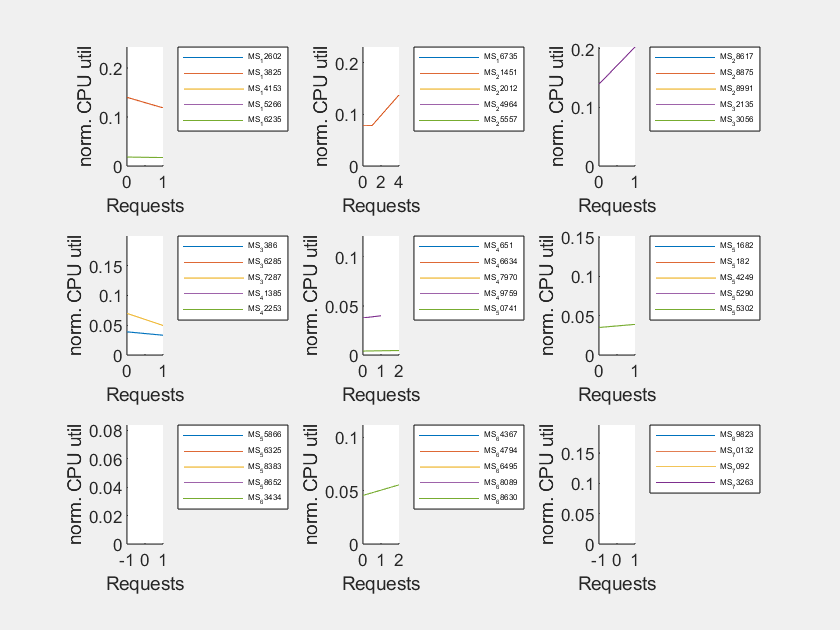

metrics_with_trace_count = join_metrics_and_traces(filtered_metrics, trace_metrics);
metrics_mean_by_trace_count = groupsummary(metrics_with_trace_count, ["ms_name", "requests"], "mean", ["cpu_utilization", "memory_utilization"]);
metrics_requests_analysis_plots(metrics_mean_by_trace_count, "cpu", {[0 Inf] "linear"});

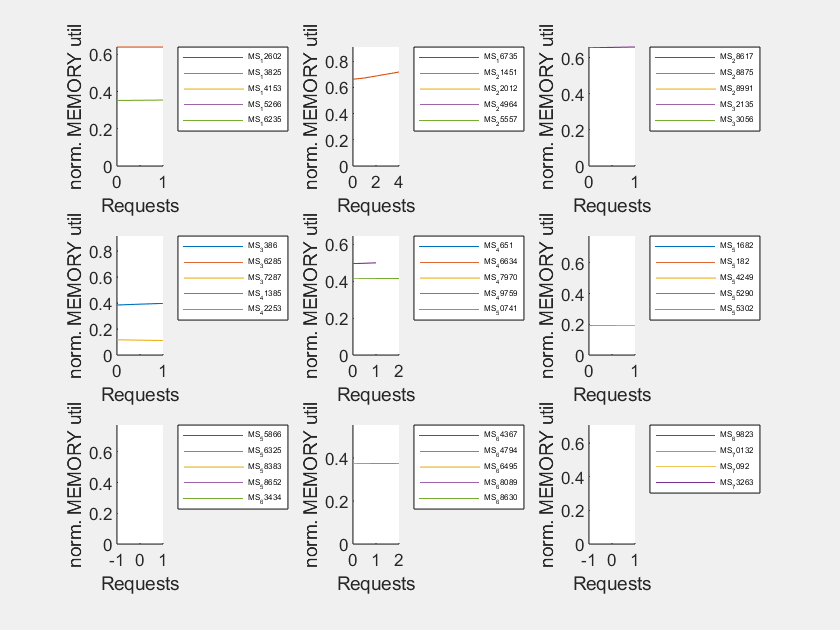

metrics_requests_analysis_plots(metrics_mean_by_trace_count, "memory", {[0 Inf] "linear"});

We combined the MSResource and MSCallGraph data in order to calculate the base-load for each service, as well as the ressource consumption per request.

Unfortunately the remaining datapoints after matching the request count of a service at the sampling timestamps are too few to yield significant and applicable results. The sampling rate for the ressource consumption would need to be increased to allow this computation.

Furthermore we find that ~50% of services we are interested in, do not have any reported metrics at all, requiring workarounds.

### Only works for MS_21451

using the 12 hours of requests matched with metric sampling

ms_21451 = metrics_mean_by_trace_count(strcmp(metrics_mean_by_trace_count.ms_name, "MS_21451"), :);
disp(ms_21451);

      ms_name       requests    GroupCount    mean_cpu_utilization    mean_memory_utilization
    ____________    ________    __________    ____________________    _______________________

    {'MS_21451'}       0           358              0.077654                  0.66281        
    {'MS_21451'}       1             1                 0.078                  0.67192        
    {'MS_21451'}       4             1               0.13733                  0.71768        



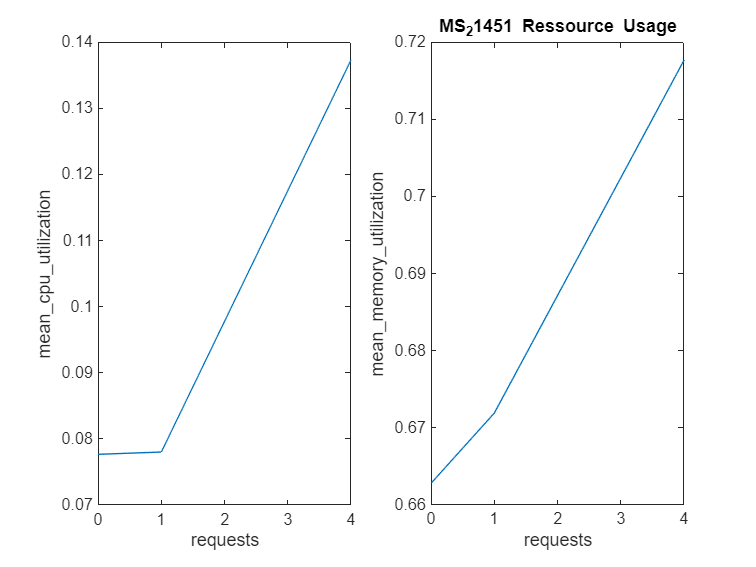

figure;
active_plot = subplot(1, 2, 1);
plot(active_plot, ms_21451, "requests","mean_cpu_utilization","DisplayName","norm. CPU util");
active_plot = subplot(1, 2, 2);
plot(active_plot, ms_21451, "requests", "mean_memory_utilization", "DisplayName", "norm. MEMORY util");
title("MS_21451 Ressource Usage")
hold off;

ms_21451_ressources = get_ressource_useage_per_request(ms_21451);
disp(ms_21451_ressources);

     ms_name      base_cpu    cpu_per_request    base_memory    memory_per_request
    __________    ________    _______________    ___________    __________________

    "MS_21451"    0.077654        0.01492          0.66281           0.013717     

